## **Jared Ham**

**Mech 513 - HW3**

**Airfoil CFD vs Thin Airfoil Theory vs Experimental Data**

airfoil_number = 'NACA0021'

ans = 2

ans = 5

ans = 2

 
C:\Users\Jared\MATLAB\Projects\HW3_Real>xfoil  0<XFOIL_RUN.txt  
 
  XFOIL Version 6.96 
  Copyright (C) 2000   Mark Drela, Harold Youngren 
 
  This software comes with ABSOLUTELY NO WARRANTY, 
    subject to the GNU General Public License. 
 
  Caveat computor 
 
 File  xfoil.def  not found 
 
   QUIT    Exit program 
 
  .OPER    Direct operating point(s) 
  .MDES    Complex mapping design routine 
  .QDES    Surface speed design routine 
  .GDES    Geometry design routine 
 
   SAVE f  Write airfoil to labeled coordinate file 
   PSAV f  Write airfoil to plain coordinate file 
   ISAV f  Write airfoil to ISES coordinate file 
   MSAV f  Write airfoil to MSES coordinate file 
   REVE    Reverse written-airfoil node ordering 
 
   LOAD f  Read buffer airfoil from coordinate file 
   NACA i  Set NACA 4,5-digit airfoil and buffer airfoil 
   INTE    Set buffer airfoil by interp

ans = 'PolarNACA0021.txt'

fid = 3

ans = 0

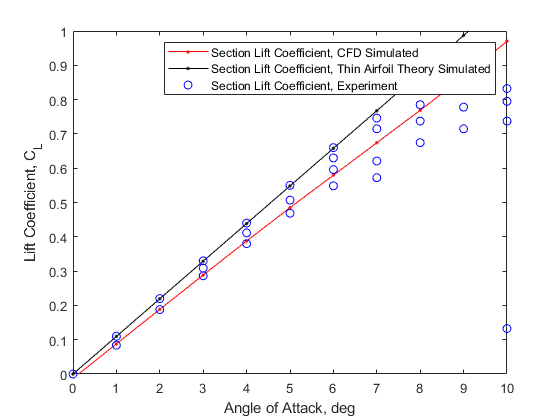

index =     91
    92
    93
    94
    95
    96
    97
    98
    99
   100


Data Collection is done, type ">> who" at the MATLAB prompt to see the outputs
CFD_AoA & CFD_CL are the angle of attack and lift coefficient as modeled using CFD
Exp_AoA & Exp_CL are the angle of attack and lift coefficient as measured by SNL using Experiment
TAS_AoA & TAS_CL are the angle of attack and lift coefficient as modeled using Thin Airfoil Assumption


MECH513_ValidationLab; %run to generate and load TAS, Xfoil and Experimental data into workspace

n = length(Exp_CL);
[Exp_linear_fit,Exp_linear_fit_gof] = fit(Exp_AoA, Exp_CL, 'poly1')

Exp_linear_fit =      Linear model Poly1:
     Exp_linear_fit(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.09066  (0.08527, 0.09605)
       p2 =     0.03087  (0.002113, 0.05963)

Exp_linear_fit_gof = struct with fields:
           sse: 0.0888
       rsquare: 0.9683
           dfe: 38
    adjrsquare: 0.9675
          rmse: 0.0483


Slope = Exp_linear_fit.p1

Slope = 0.0907

y_intercept = Exp_linear_fit.p2;
rsquare = Exp_linear_fit_gof.rsquare

rsquare = 0.9683

residuals_squared = ((Exp_AoA * Slope) - Exp_CL).^2;
s = sqrt(1/(n-1) * sum(residuals_squared))   % should be 0.0506

s = 0.0570